## Variaveis globais

N = 10000;

## (a)

T = 1000; 
chaves = 10;

equal = 0;

for i=1:N
    array = randi(T,1,chaves);
        if(length(unique(array)) == chaves)
        else 
            equal = equal +1;
        end
end

prob = equal/N

prob = 0.0476

## (b)

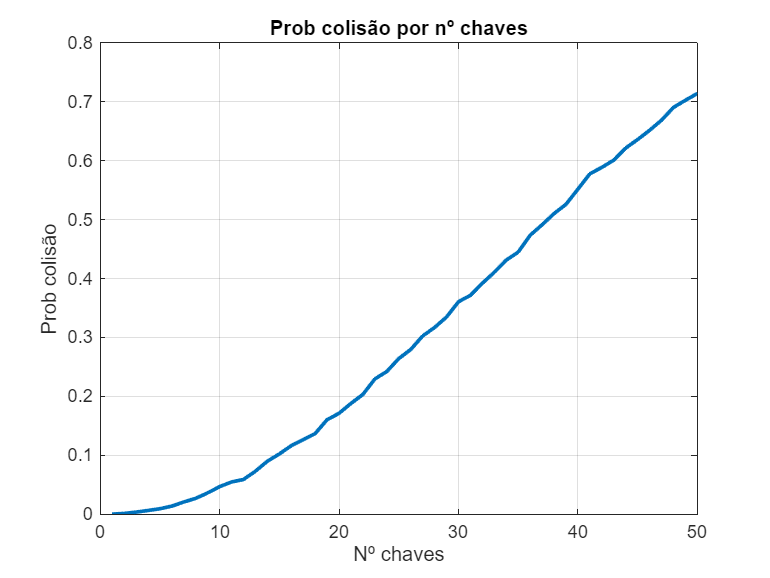

Nchaves = 50; 
prob_colisao = zeros(1, Nchaves);

for chaves = 1:Nchaves
    equal = 0;
    for i = 1:N
        array = randi(T, 1, chaves);
        if length(unique(array)) < chaves
            equal = equal + 1;
        end
    end
    prob_colisao(chaves) = equal / N;
end

figure;
plot(1:Nchaves, prob_colisao, 'LineWidth', 2);
xlabel('Nº chaves');
ylabel('Prob colisão');
title('Prob colisão por nº chaves');
grid on;

## (c)

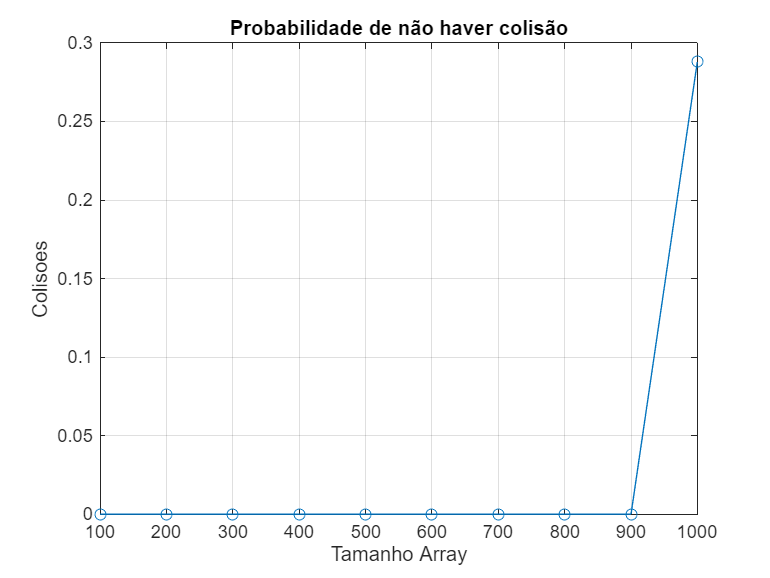

T = 100:100:1000;
chaves_c = 50;
%N = 10000;

y = zeros(1,length(T));

for i=length(T)
    T_atual = T(i);
    diferente= 0;
    for j=5:N
        array = randi(T_atual,1,chaves_c);
        if(length(unique(array)) == chaves_c)
            diferente = diferente + 1;
        end
    end
    y(i)=diferente/N;
end

figure;
plot(T,y,'-o');
xlabel('Tamanho Array');
ylabel('Colisoes'); 
title('Probabilidade de não haver colisão');
grid on;